% This program extratcts of the data from stationary extrusion of gelatin.
% 
% Material is 4.76% w/w gelatin
% Inner diameter of cylinder and syringe are 16 and 22.5 mm, repectively.
% Operating temperature at 25 degreeC
% 
% system_t  is time from the system log.
% system_ps is pressure from the system log.
% system_lc is the inner longitudinal distance of cylinder from the system log.
% video_ls  is the inner longitudinal distance of syringe from the video.
% model_ls  is the inner longitudinal distance of syringe from the air model.

feedrate = '200'; % feedrate of cylinder in micron/s (available feedrate values: 200, 400, 600, and 800)

data_filename = ['stationary_dataset_f' feedrate '.mat'];
load(data_filename)

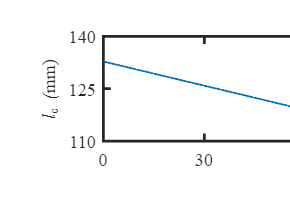

figure
figure
fig = gcf;
fig.Units = 'centimeters';
fig.Position = [10 5 15.5 11];

color = colororder('gem');

ax1 = subplot(3,1,1);

xline(60,'--k','LineWidth',1);
hold on
xline(180,'--k','LineWidth',1);
l1 = plot(system_t,video_ls,'-','LineWidth',1);
hold on
l2 = plot(system_t(1:size(model_ls,1)),model_ls,'-','LineWidth',1);

ax1.Units = 'centimeters';
ax1.FontName = 'Times New Roman';
ax1.FontSize = 10;
ax1.LineWidth = 1.5;
ax1.Box = 'on';
ax1.Position = [2 8.25 12 2];
xlim(ax1,[0 185])
xticks(ax1,0:30:180)
if max(video_ls) > max(model_ls)
    max_ls = max(video_ls);
else
    max_ls = max(model_ls);
end
if min(video_ls) < min(model_ls)
    min_ls = min(video_ls);
else
    min_ls = min(model_ls);
end
ylim(ax1,[floor(min_ls) ceil(max_ls)])
yticks(linspace(floor(min_ls),ceil(max_ls),3))

xlabel(ax1,'\fontname{Times New Roman}\itt \rm(s)','FontSize',10)
ylabel(ax1,'\fontname{Times New Roman}\itl_{\rms}\fontname{Times New Roman} (\rmmm)','FontSize',10)

legend([l1 l2],{'Video','Model'},'Location','northwest','NumColumns',1)

ax2 = subplot(3,1,2);

xline(60,'--k','LineWidth',1);
hold on
xline(180,'--k','LineWidth',1);
l3 = plot(system_t,system_ps,'-','LineWidth',1);

ax2.Units = 'centimeters';
ax2.FontName = 'Times New Roman';
ax2.FontSize = 10;
ax2.LineWidth = 1.5;
ax2.Box = 'on';
ax2.Position = [2 4.75 12 2];
xlim(ax2,[0 185])
xticks(ax2,0:30:180)
ylim([floor(min(system_ps)/10)*10 ceil(max(system_ps)/10)*10])
yticks(linspace(floor(min(system_ps)/10)*10,ceil(max(system_ps)/10)*10,3))

xlabel(ax2,'\fontname{Times New Roman}\itt \rm(s)','FontSize',10)
ylabel(ax2,'\fontname{Times New Roman}\itP_{\rms}\fontname{Times New Roman} (\rmkPa)','FontSize',10)

ax3 = subplot(3,1,3);

xline(60,'--k','LineWidth',1);
hold on
xline(180,'--k','LineWidth',1);
l4 = plot(system_t,system_lc,'-','LineWidth',1);

ax3.Units = 'centimeters';
ax3.FontName = 'Times New Roman';
ax3.FontSize = 10;
ax3.LineWidth = 1.5;
ax3.Box = 'on';
ax3.Position = [2 1.25 12 2];
xlim(ax3,[0 185])
xticks(ax3,0:30:180)
ylim([floor(min(system_lc)/10)*10 ceil(max(system_lc)/10)*10])
yticks(linspace(floor(min(system_lc)/10)*10,ceil(max(system_lc)/10)*10,3))

xlabel(ax3,'\fontname{Times New Roman}\itt \rm(s)','FontSize',10)
ylabel(ax3,'\fontname{Times New Roman}\itl_{\rmc}\fontname{Times New Roman} (\rmmm)','FontSize',10)